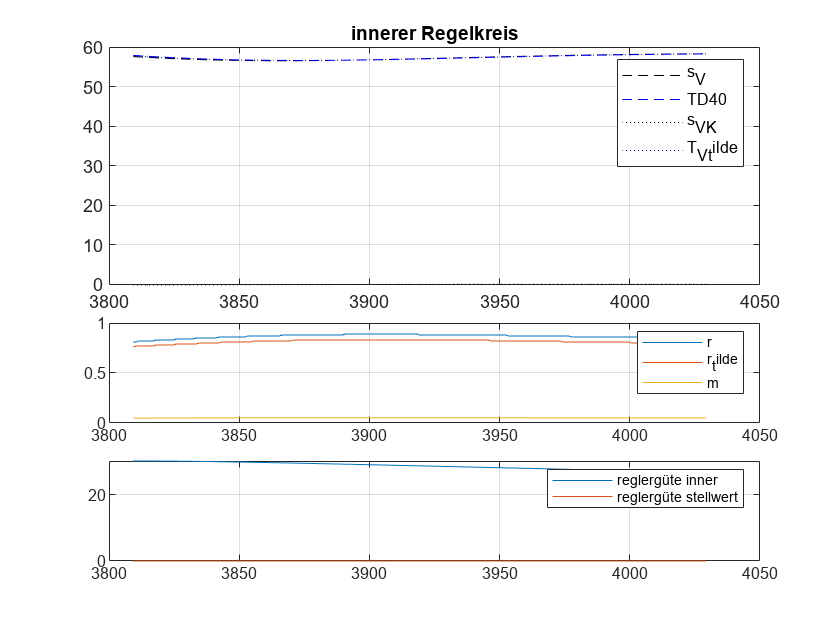

Unrecognized function or variable 'p'.

clear all 
while true
    clf
    try
        p = readtable("Raspberry pi git\ABB_pi\Monitor/log.txt");
        p = sortrows(p,"reihenfolge");
    catch exception
    end
    l = size(p); l=l(1);
    start = max(1,l-200);
    p = p(start:end,:);
    
    
    subplot(4,1,[1 2])
    plot(p.reihenfolge,p.s_V,'k','LineStyle','--')
    hold on
    plot(p.reihenfolge,p.T_D40,'b','LineStyle','--')
    plot(p.reihenfolge,p.s_V_K,'k','LineStyle',':')
    plot(p.reihenfolge,p.T_V_tilde,'b','LineStyle',':')
    legend({'s_V','TD40','s_V_K','T_V_tilde'})
    title('innerer Regelkreis')
    grid on
    subplot(4,1,3)
    plot(p.reihenfolge,p.r)
    hold on
    plot(p.reihenfolge,p.r_tilde)
    plot(p.reihenfolge,p.m)
    legend({'r','r_tilde','m'})
    grid on
    subplot(4,1,4)
    plot(p.reihenfolge,p.reglerguete_Misch)
    hold on
    plot(p.reihenfolge,p.reglerguete_stellgroesse)
    grid on
    legend({'reglergüte inner','reglergüte stellwert'})
    hold off


    drawnow


%     subplot(12,1,4)
%     subplot(12,1,[5 6])
%     subplot(12,1,7)
%     subplot(12,1,8)
%     subplot(12,1,[9 10])
%     subplot(12,1,[11 12])

  
    
    
    
    
    
    pause(1)
end